Collect scan data

% scan 1, at origin, facing in i hat g direction
neato_pos = [0 0]

neato_pos =      0     0


neato_heading = [1 0]

neato_heading =      1     0



% scan 2, middle of gauntlet, facing 315 degrees ccw from i hat g direction
% neato_pos = [0 -2]
% neato_heading = [1 -1]

placeNeato(neato_pos(1),neato_pos(2),neato_heading(1),neato_heading(2))

Unrecognized function or variable 'placeNeato'.

pause(2)
[r, theta] = scan();

save('test/test_scan.mat', 'r', 'theta')

Convert scan data to global data

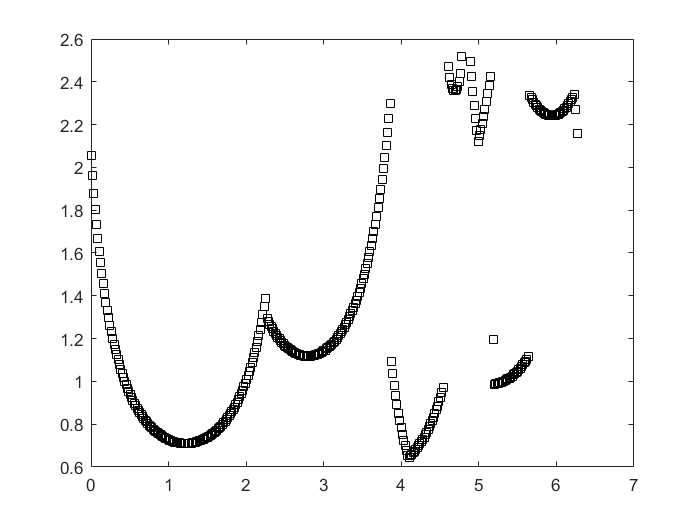

load test/test_scan.mat
figure
plot(theta, r, 'ks')

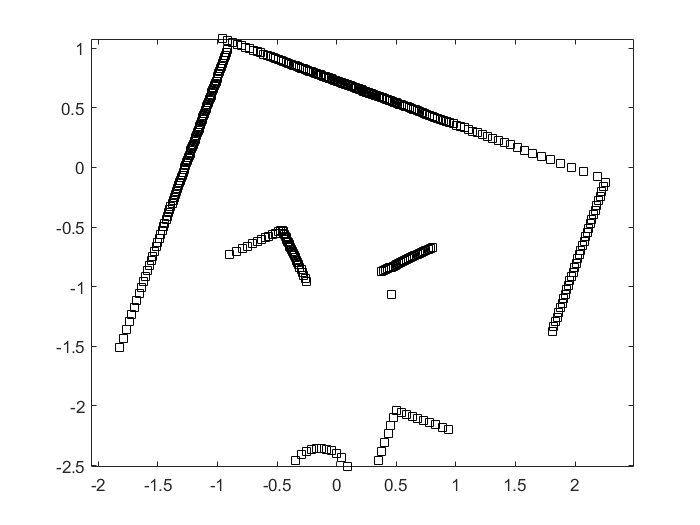


neato_orientation = atan2(neato_heading(2), neato_heading(1));
neato_orientation * 180 /pi;
points = convertLidarToGlobal(r, theta, neato_pos, neato_orientation);
figure
plot(points(:,1), points(:,2), 'ks'); axis equal;

save('test/converted_scan.mat', 'points')

Test RANSAC line and circle fitting

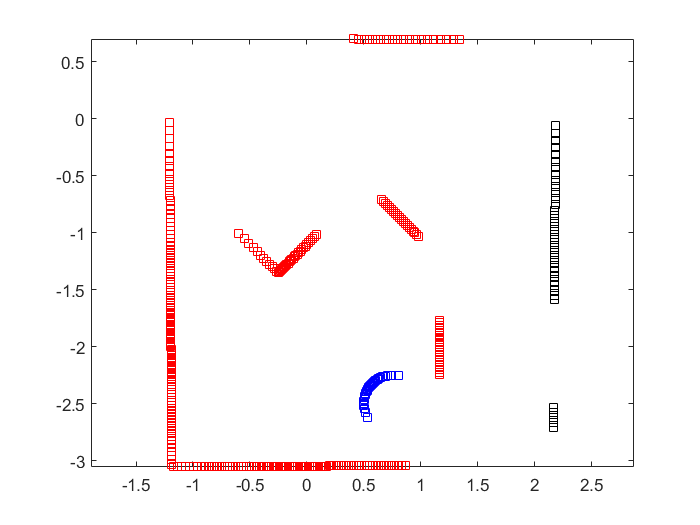

clf;
load test/converted_scan2.mat
figure
plot(points(:,1), points(:,2), 'ks'); hold on; axis equal;
bob_radius = 0.25; % radius of bob is given; 0.25

% [inlier_set, outlier_set] = lineRansac(points, 1000, 0.05);

[line_inliers, circle_inliers, circle_center] = detectObjects(points, bob_radius);
plot(line_inliers(:,1), line_inliers(:,2), 'rs');
plot(circle_inliers(:,1), circle_inliers(:,2), 'bs');

figure
syms x y
[xs, ys] = meshgrid(-2:1:3, -3.5:1:1);
p_field = create_potential_field(line_inliers, circle_inliers);

done


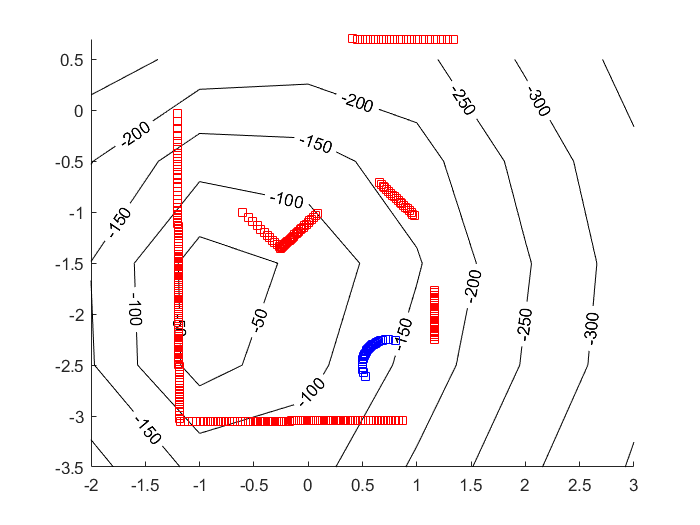

v = double(subs(p_field, {x, y}, {xs, ys}));
hold on
contour(xs, ys, v, 'k', 'ShowText', 'On')
plot(line_inliers(:,1), line_inliers(:,2), 'rs');
plot(circle_inliers(:,1), circle_inliers(:,2), 'bs');